clf;
%Valores inicales

m0 = 4*pi*(10^-7); %miu0

a = 2;
A = pi*a^2; %area del circulo
R = 0.0000001;
g = 9.81;
IN = 1000;
U = IN*A; %miu.
m = 300;
N = 100000;

x0 = 70;
dt = 0.01;
h = dt;
v0 = 0;
t0 = 0;
tf = 7;

t = t0:h:tf; %vector de tiempo


$$\mathrm{Fx}=-\frac{27x^3 {\mu_0 }^3 \mu^2 a^6 {V_x }^2 A}{8R^2 {\left(a^2 +x^2 \right)}^{\frac{15}{2}} }$$



$$a=-g-\left(\frac{\textrm{Fx}}{m}\right)$$



$$a=-g+$$

$$\frac{27x^3 {\mu_0 }^3 \mu^2 a^6 {V_x }^2 A}{8mR^2 {\left(a^2 +x^2 \right)}^{\frac{15}{2}} }$$



$$V\;=V_i +\mathrm{at}$$


aceleracion = @(x,Vx) -g + ((27*(x^3)*(m0^3)*(U^2)*(a^6)*(Vx^2)*A)/(8*m*(R^2)*(a^2+x^2)^(15/2)))*N; 
velocidad = @(Vx,ace) Vx + ace*h;

[tt,acelacel,velvel,pospos] = met_RK4Mod(aceleracion,velocidad, h, t0, tf, aceleracion(x0,v0), v0, x0);


$$\mathrm{FEM}=\frac{3\mu_0 \mu {a^2 \mathrm{xV}}_x }{2{\left(a^2 +x^2 \right)}^{\frac{5}{2}} }$$


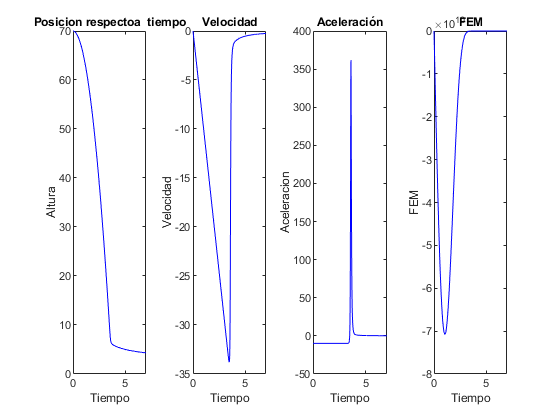

fem = @(x,Vx) (3.*m0.*U.*(a.^2).*x.*Vx)/2.*(a.^2+x.^2).^(5/2);
%Se grafica el resultado
tiledlayout(1,4);
nexttile
plot(t,pospos,'b')
title('Posicion respectoa  tiempo')
xlabel('Tiempo')
ylabel('Altura')
nexttile
plot(t,velvel,'b')
title('Velocidad')
xlabel('Tiempo')
ylabel('Velocidad')
nexttile
plot(t,acelacel,'b');
title('Aceleración')
xlabel('Tiempo')
ylabel('Aceleracion')
nexttile
plot(t,fem(pospos,velvel),'b');
title('FEM')
xlabel('Tiempo')
ylabel('FEM')

Solución Numérica por el m**étodo de RK Grado 4.**

function [x,acel,vel,pos] = met_RK4Mod(f1,f2, h, inicio, fin, acel_inicial, vel_inicial, pos_inicial)
    x = inicio:h:fin;
    acel = zeros(1,length(x));
    vel = zeros(1,length(x));
    pos = zeros(1,length(x));
    acel(1) = acel_inicial;
    vel(1) = vel_inicial;
    pos(1) = pos_inicial;
    for i=1:(length(x)-1)
        k1 = f1(pos(i), vel(i));
        k2 = f1(pos(i)+(1/2*h), vel(i)+(1/2*k1*h));
        k3 = f1(pos(i)+(1/2*h), vel(i)+(1/2*k2*h));
        k4 = f1(pos(i)+h, vel(i) + k3*h);
        vel(i+1) = vel(i)+1/6*(k1+2*k2+2*k3+k4)*h;
        
        acel(i) = f1(pos(i), vel(i)); %rellenar vector de aceleracion
        
        l1 = f2(vel(i),acel(i));
        l2 = f2(vel(i)+(1/2*h),acel(i)+(1/2*h*l1));
        l3 = f2(vel(i)+(1/2*h),acel(i)+(1/2*h*l2));
        l4 = f2(vel(i)+h,acel(i)+(l3*h));
        pos(i+1) = pos(i)+1/6*(l1+2*l2+2*l3+l4)*h;
    end
end